# 3R Manipulator kinematics

## Using 3R robot object from RTB

clear
mdl_3link3d
R3

 
R3 = 
 
3link 3D:: 3 axis, RRR, stdDH, slowRNE                           
 - Spong p106;                                                   
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          1|          0|     1.5708|          0|
|  2|         q2|          0|          2|          0|          0|
|  3|         q3|          0|          3|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


### Modiffying the DH Paramenters

R3.links(1, 1).d=7

 
R3 = 
 
3link 3D:: 3 axis, RRR, stdDH, slowRNE                           
 - Spong p106;                                                   
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          7|          0|     1.5708|          0|
|  2|         q2|          0|          2|          0|          0|
|  3|         q3|          0|          3|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


R3.links(1, 2).a=2

 
R3 = 
 
3link 3D:: 3 axis, RRR, stdDH, slowRNE                           
 - Spong p106;                                                   
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          7|          0|     1.5708|          0|
|  2|         q2|          0|          2|          0|          0|
|  3|         q3|          0|          3|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


R3.links(1, 3).a=1

 
R3 = 
 
3link 3D:: 3 axis, RRR, stdDH, slowRNE                           
 - Spong p106;                                                   
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          7|          0|     1.5708|          0|
|  2|         q2|          0|          2|          0|          0|
|  3|         q3|          0|          1|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


### Using Teach

Calculate the result of the final pose (i.e. Forward Kinematics) for the following joint angles: [0  0  0], [0 π/2  0] and (0 π/2  π/6).

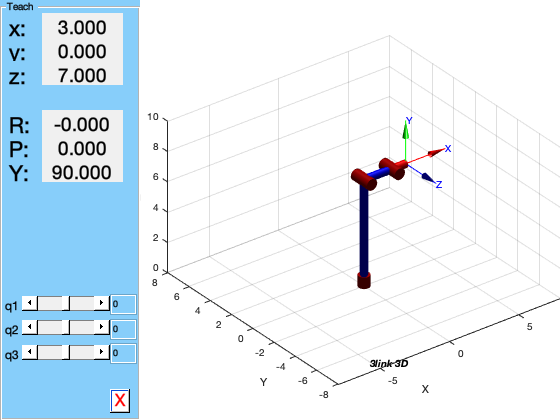


syms theta_1 theta_2 theta_3 L_0 L_1 L_2 real
R3.plot([0 0 0],'zoom',1.5)
axis([-8 8 -8 8 0 10])
R3.teach

FK_RTB=R3.fkine([0 0 0])

 

FK_RTB = 
         1         0         0         3
         0         0        -1         0
         0         1         0         7
         0         0         0         1


RPY_RTB=tr2rpy(FK_RTB)

RPY_RTB =     1.5708         0         0


### Forward Kinematics by hand (Std)

Applying Post Multiplication find $^{0}_{EE}T$

syms theta_1 theta_2 theta_3 L_0 L_1 L_2 real
FK_hand= simplify(transl(0,0,L_0)*trotz(theta_1)*trotx(pi/2)*trotz(theta_2)*transl(L_1,0,0)*trotz(theta_3)*transl(L_2,0,0))

$$FK\_hand = \begin{array}{l} \left(\begin{array}{cccc} \cos\left(\theta_{2}+\theta_{3}\right)\,\cos\left(\theta_{1}\right) & -\sin\left(\theta_{2}+\theta_{3}\right)\,\cos\left(\theta_{1}\right) & \sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right)\,\sigma_{1}\\ \cos\left(\theta_{2}+\theta_{3}\right)\,\sin\left(\theta_{1}\right) & -\sin\left(\theta_{2}+\theta_{3}\right)\,\sin\left(\theta_{1}\right) & -\cos\left(\theta_{1}\right) & \sin\left(\theta_{1}\right)\,\sigma_{1}\\ \sin\left(\theta_{2}+\theta_{3}\right) & \cos\left(\theta_{2}+\theta_{3}\right) & 0 & L_{0}+L_{2}\,\sin\left(\theta_{2}+\theta_{3}\right)+L_{1}\,\sin\left(\theta_{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=L_{2}\,\cos\left(\theta_{2}+\theta_{3}\right)+L_{1}\,\cos\left(\theta_{2}\right) \end{array}$$

FK_hand= transl(0,0,7)*trotz(0)*trotx(pi/2)*trotz(0)*transl(2,0,0)*trotz(0)*transl(1,0,0)

FK_hand =      1     0     0     3
     0     0    -1     0
     0     1     0     7
     0     0     0     1


Do the same for:

R3.plot( [0 pi/2  0],'zoom',1.5)
axis([-8 8 -8 8 0 10])
R3.teach

R3.plot( [0 pi/2  pi/6])
axis([-8 8 -8 8 0 10])
R3.teach
FK_RTB=R3.fkine([0 pi/2 pi/6])

## DH Parameters


$$DHP [\theta \ d \ a  \ \alpha]$$


### Frame assignement

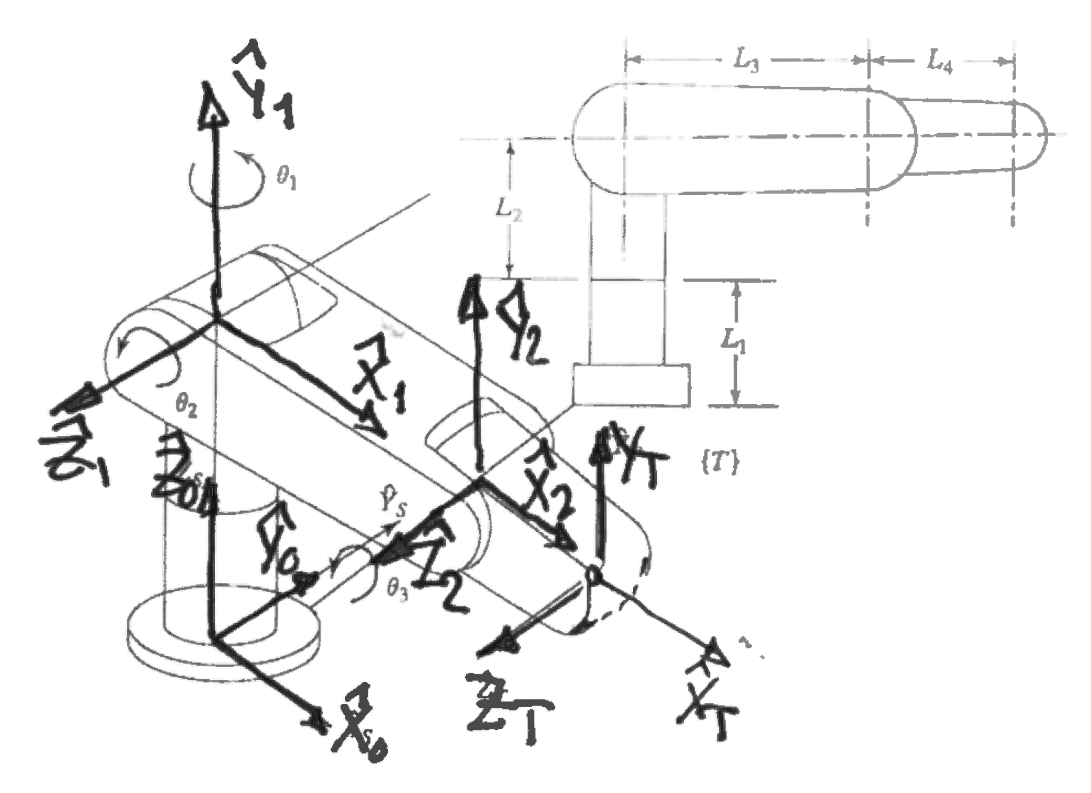

DHP_L1=[theta_1 7 0 pi/2]

$$DHP\_L1 = \left(\begin{array}{cccc} \theta_{1} & 7 & 0 & \frac{\pi }{2} \end{array}\right)$$

DHP_L2=[theta_2 0 2 0]

$$DHP\_L2 = \left(\begin{array}{cccc} \theta_{2} & 0 & 2 & 0 \end{array}\right)$$

DHP_L3=[theta_3 0 1 0]

$$DHP\_L3 = \left(\begin{array}{cccc} \theta_{3} & 0 & 1 & 0 \end{array}\right)$$

### Neibouring Transformation

T_1_0=transl(0,0,7)*trotz(theta_1)*trotx(pi/2)

$$T\_1\_0 = \left(\begin{array}{cccc} \cos\left(\theta_{1}\right) & 0 & \sin\left(\theta_{1}\right) & 0\\ \sin\left(\theta_{1}\right) & 0 & -\cos\left(\theta_{1}\right) & 0\\ 0 & 1 & 0 & 7\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_2_1=trotz(theta_2)*transl(2,0,0)

$$T\_2\_1 = \left(\begin{array}{cccc} \cos\left(\theta_{2}\right) & -\sin\left(\theta_{2}\right) & 0 & 2\,\cos\left(\theta_{2}\right)\\ \sin\left(\theta_{2}\right) & \cos\left(\theta_{2}\right) & 0 & 2\,\sin\left(\theta_{2}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_3_2=trotz(theta_3)*transl(1,0,0)

$$T\_3\_2 = \left(\begin{array}{cccc} \cos\left(\theta_{3}\right) & -\sin\left(\theta_{3}\right) & 0 & \cos\left(\theta_{3}\right)\\ \sin\left(\theta_{3}\right) & \cos\left(\theta_{3}\right) & 0 & \sin\left(\theta_{3}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T_3_0=simplify(T_1_0*T_2_1*T_3_2)

$$T\_3\_0 = \begin{array}{l} \left(\begin{array}{cccc} \cos\left(\theta_{2}+\theta_{3}\right)\,\cos\left(\theta_{1}\right) & -\sin\left(\theta_{2}+\theta_{3}\right)\,\cos\left(\theta_{1}\right) & \sin\left(\theta_{1}\right) & \cos\left(\theta_{1}\right)\,\sigma_{1}\\ \cos\left(\theta_{2}+\theta_{3}\right)\,\sin\left(\theta_{1}\right) & -\sin\left(\theta_{2}+\theta_{3}\right)\,\sin\left(\theta_{1}\right) & -\cos\left(\theta_{1}\right) & \sin\left(\theta_{1}\right)\,\sigma_{1}\\ \sin\left(\theta_{2}+\theta_{3}\right) & \cos\left(\theta_{2}+\theta_{3}\right) & 0 & \sin\left(\theta_{2}+\theta_{3}\right)+2\,\sin\left(\theta_{2}\right)+7\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta_{2}+\theta_{3}\right)+2\,\cos\left(\theta_{2}\right) \end{array}$$

Numerical example

FK_3R=R3.fkine([pi/6 0 0 ])

theta_1=atan2(FK_3R.t(2),FK_3R.t(1))
pi/6
trotz(-theta_1)*FK_3R.T

Notice that 

syms theta_1 theta_2 theta_3 L_1 L_2 real
FK= simplify(trotz(0)*trotx(pi/2)*trotz(theta_2)*transl(L_1,0,0)*trotz(theta_3)*transl(L_2,0,0))



## Building the 3R Manipulator Object

clear L
%            theta    d        a    alpha     Std/Mdh
L(1) = Link([  0      7        0     pi/2       0], 'standard');
L(2) = Link([  0      0        2      0          0], 'standard');
L(3) = Link([  0      0        1      0          0], 'standard');
%
% some useful poses
%
qz = [0 0 0]; % zero angles, L shaped pose
qr = [0 pi/2 0]; % ready pose, arm up


R3_FIB = SerialLink(L, 'name', 'R3_FIB',...
                           'manufacturer', 'ROB',...
                           'comment', 'L11');
clear L

## FK from R3_FIB Object

R3_FIB.fkine(qz)

 

ans = 
         1         0         0         3
         0         0        -1         0
         0         1         0         7
         0         0         0         1
